3.1

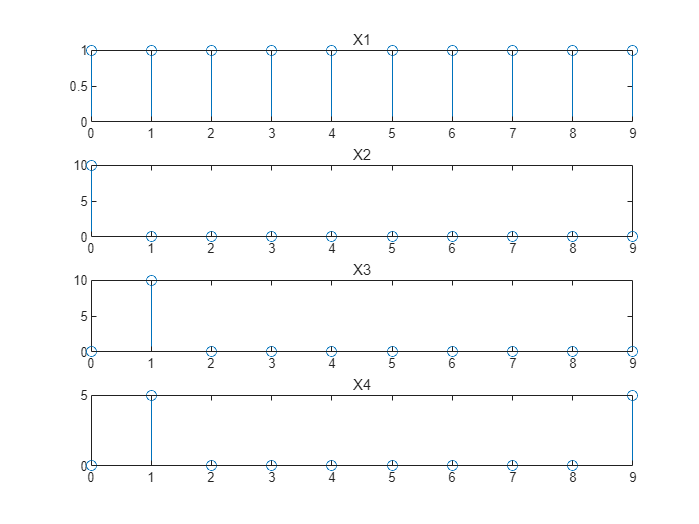

clc,clear ,close all;
n=0:9;
x1=(n==0);
x2=ones(size(n));
x3=exp(1i*2*pi*n/10);
x4=cos(2*pi*n/10);

figure
subplot(4,1,1);
X1=DFTsum(x1);
stem(n,abs(X1));title('X1');
subplot(4,1,2);
X2=DFTsum(x2);
stem(n,abs(X2));title('X2');
subplot(4,1,3);
X3=DFTsum(x3);
stem(n,abs(X3));title('X3');
subplot(4,1,4);
X4=DFTsum(x4);
stem(n,abs(X4));title('X4');

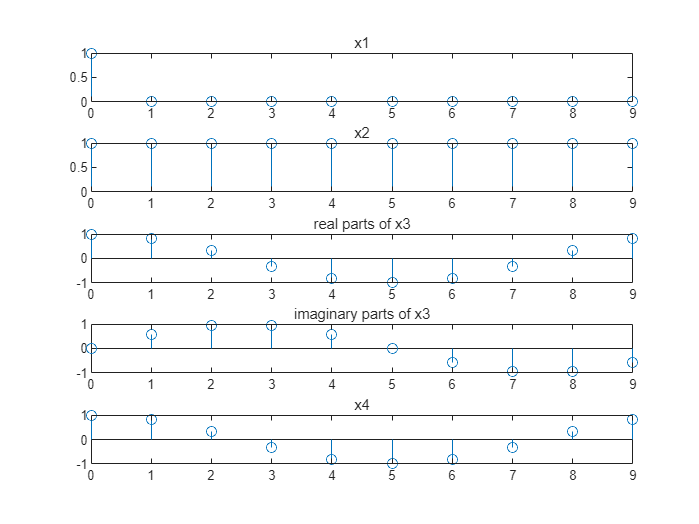


figure
subplot(5,1,1);
stem(n,x1);title('x1');
subplot(5,1,2);
stem(n,x2);title('x2');
subplot(5,1,3);
stem(n,real(x3));title('real parts of x3');
subplot(5,1,4);
stem(n,imag(x3));title('imaginary parts of x3');
subplot(5,1,5);
stem(n,x4);title('x4');

Xrc1=IDFTsum(X1);
Xrc2=IDFTsum(X2);
Xrc3=IDFTsum(X3);
Xrc4=IDFTsum(X4);

figure
subplot(5,1,1);
stem(n,real(Xrc1));title('x1');
subplot(5,1,2);
stem(n,real(Xrc2));title('x2');
subplot(5,1,3);
stem(n,real(Xrc3));title('real parts of x3');
subplot(5,1,4);
stem(n,imag(Xrc3));title('imaginary parts of x3');
subplot(5,1,5);
stem(n,real(Xrc4));title('x4');

3.2

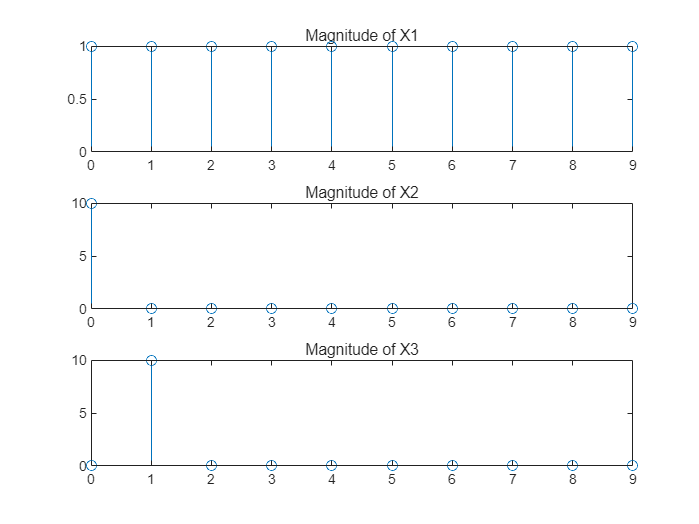

clear;clc;close;
n=(0:9)';

x1=(n==0);
x2=ones(size(n));
x3=exp((1i*2*pi*n)/10);

X1=DFTmatrix(10)*x1;
X2=DFTmatrix(10)*x2;
X3=DFTmatrix(10)*x3;

figure
subplot(3,1,1);
stem(n,abs(X1));title('Magnitude of X1')
subplot(3,1,2);
stem(n,abs(X2));title('Magnitude of X2')
subplot(3,1,3);
stem(n,abs(X3));title('Magnitude of X3')

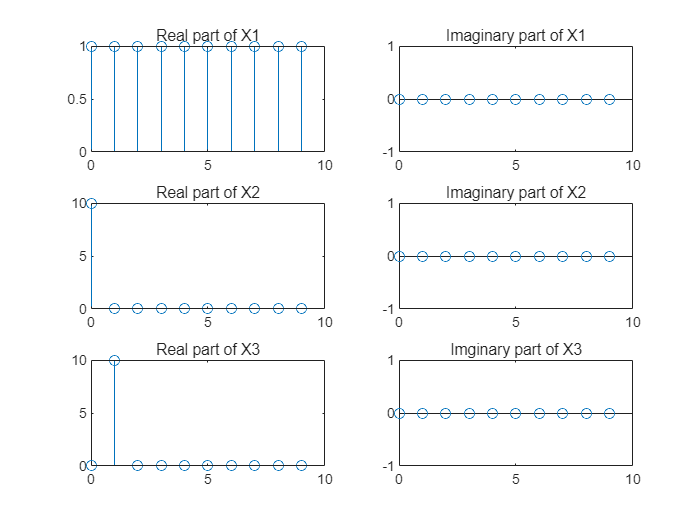


figure
subplot(3,2,1);
stem(n,real(X1));title('Real part of X1')
subplot(3,2,2);
stem(n,imag(X1));title('Imaginary part of X1')
subplot(3,2,3);
stem(n,real(X2));title('Real part of X2')
subplot(3,2,4);
stem(n,imag(X2));title('Imaginary part of X2');ylim([-1,1])
subplot(3,2,5);
stem(n,real(X3));title('Real part of X3')
subplot(3,2,6);
stem(n,imag(X3));title('Imginary part of X3');ylim([-1,1])


A5=DFTmatrix(5)

A5 =    1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i
   1.0000 + 0.0000i   0.3090 - 0.9511i  -0.8090 - 0.5878i  -0.8090 + 0.5878i   0.3090 + 0.9511i
   1.0000 + 0.0000i  -0.8090 - 0.5878i   0.3090 + 0.9511i   0.3090 - 0.9511i  -0.8090 + 0.5878i
   1.0000 + 0.0000i  -0.8090 + 0.5878i   0.3090 - 0.9511i   0.3090 + 0.9511i  -0.8090 - 0.5878i
   1.0000 + 0.0000i   0.3090 + 0.9511i  -0.8090 + 0.5878i  -0.8090 - 0.5878i   0.3090 - 0.9511i


B5=IDFTmatrix(5)

B5 =    0.2000 + 0.0000i   0.2000 + 0.0000i   0.2000 + 0.0000i   0.2000 + 0.0000i   0.2000 + 0.0000i
   0.2000 + 0.0000i   0.0618 + 0.1902i  -0.1618 + 0.1176i  -0.1618 - 0.1176i   0.0618 - 0.1902i
   0.2000 + 0.0000i  -0.1618 + 0.1176i   0.0618 - 0.1902i   0.0618 + 0.1902i  -0.1618 - 0.1176i
   0.2000 + 0.0000i  -0.1618 - 0.1176i   0.0618 + 0.1902i   0.0618 - 0.1902i  -0.1618 + 0.1176i
   0.2000 + 0.0000i   0.0618 - 0.1902i  -0.1618 - 0.1176i  -0.1618 + 0.1176i   0.0618 + 0.1902i


C=B5*A5

C =    1.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i
  -0.0000 + 0.0000i   1.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 - 0.0000i   0.0000 - 0.0000i
  -0.0000 + 0.0000i  -0.0000 + 0.0000i   1.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 - 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   1.0000 - 0.0000i  -0.0000 - 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i  -0.0000 - 0.0000i   1.0000 + 0.0000i


3.3

clear;clc;close;
r=12;
N=2^r;
n=0:N-1;
x=cos(2*pi*n/10);
A=DFTmatrix(N);

starttime1=cputime;
X1=DFTsum(x);
endtime1=cputime-starttime1

endtime1 = 2.4062


starttime2=cputime;
X2=A*x';
endtime2=cputime-starttime2

endtime2 = 0.0781